# Excercise: Normal and Shear Stress on a Vertical Fault

clc, clear

## 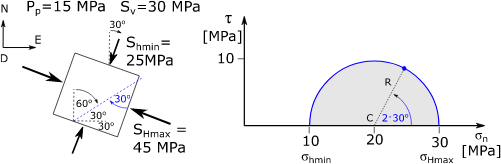

from : [https://dnicolasespinoza.github.io/node38.html#fig:3DMohrCircle](https://dnicolasespinoza.github.io/node38.html#fig:3DMohrCircle) 

My sketch

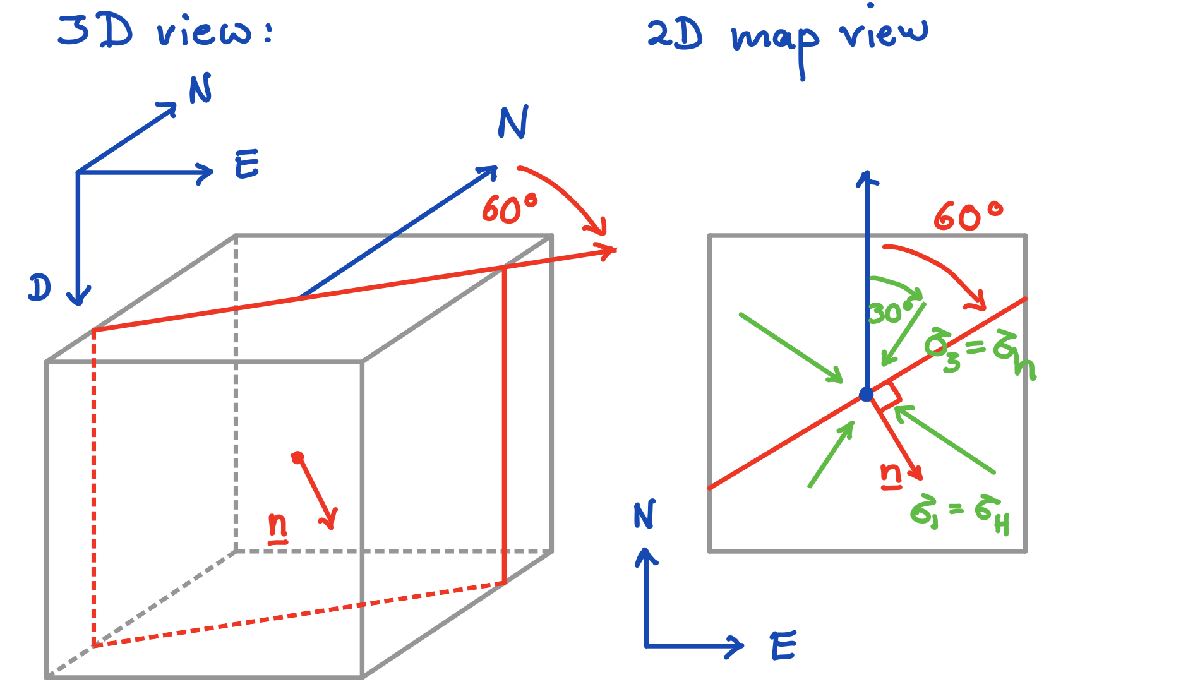

## General rotation matrix

Q = @(r,theta) r*r' + cos(theta)*(eye(3) - r*r') + sin(theta) *[0 -r(3) r(2);r(3) 0 -r(1);-r(2) r(1) 0];

Rh = @(theta) [cos(theta) -sin(theta) 0;...
               sin(theta)  cos(theta) 0;...
               0           0          0];

## Geographic coordinate system

For the geographical considerations below we introduce the N-E-D geographic coordinate system $\{\mathbf{e}_i\}$:

$\mathbf{e}_1$= North, $\mathbf{e}_2$= East, $\mathbf{e}_3$= Down 

This system is right handed.

e1_ned = [1;0;0]; e2_ned = [0;1;0]; e3_ned = [0;0;1];

Note that $\mathbf{e}_3$ is not '-1', because the third axis is pointing down.

## Fault orientation

- Strike azimuth = 60 deg North

- Fault dip = 90 deg

dip_rad = deg2rad(45);
strike_rad = deg2rad(60); 

% Analytic tensors
QDa = 1/sqrt(2)*[sqrt(2) 0 0;0 1 -1;0 1 1]

QDa =     1.0000         0         0
         0    0.7071   -0.7071
         0    0.7071    0.7071


QSa = 1/2*[1 -sqrt(3) 0;sqrt(3) 1 0;0 0 2]

QSa =     0.5000   -0.8660         0
    0.8660    0.5000         0
         0         0    1.0000


na = [-sqrt(3); 1; -2]/2/sqrt(2)

na =    -0.6124
    0.3536
   -0.7071


% Numerical tensors
QD = Q(e1_ned,dip_rad) % should this have a minus sign?!?

QD =     1.0000         0         0
         0    0.7071   -0.7071
         0    0.7071    0.7071


QS = Q(e3_ned,strike_rad)

QS =     0.5000   -0.8660         0
    0.8660    0.5000         0
         0         0    1.0000


n_ned = QS*QD*(-e3_ned) % fault orientation in NED frame

n_ned =    -0.6124
    0.3536
   -0.7071



norm(n_ned)

ans = 1

## Stress state

Principal stresses

sig_1 = 45; % MPa
sig_2 = 30; % MPa
sig_3 = 25; % MPa
p = 0;
sigma_p = [sig_1-p     0       0;...
             0     sig_2-p     0;...
             0       0     sig_3-p]

sigma_p =     45     0     0
     0    30     0
     0     0    25


Principal directions

% Old calculation
theta_stress = pi/6; % azimuth of sig_h
ep2 = e3_ned;                  % sig_v = sig_2 is intermediate

QS_Shmin_a = 1/2*[sqrt(3) -1 0;1 sqrt(3) 0;0 0 2]

QS_Shmin_a =     0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000


% New calculation
strike_Shmin = deg2rad(30); 
QS_Shmin = Q(e3_ned,strike_Shmin)

QS_Shmin =     0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000


v3_ned = QS_Shmin*e1_ned

v3_ned =     0.8660
    0.5000
         0


v2_ned = e3_ned

v2_ned =      0
     0
     1


v1_ned = cross(v2_ned,v3_ned)

v1_ned =    -0.5000
    0.8660
         0


ep1 = v1_ned; ep2 = v2_ned; ep3 = v3_ned;

## Change of basis matrix

% Old calcuation
A = [e1_ned'*ep1 e1_ned'*ep2 e1_ned'*ep3;...
     e2_ned'*ep1 e2_ned'*ep2 e2_ned'*ep3;...
     e3_ned'*ep1 e3_ned'*ep2 e3_ned'*ep3]

A =    -0.5000         0    0.8660
    0.8660         0    0.5000
         0    1.0000         0


 det(A) % check rotation matrix 

ans = 1

 A'*A   % Check orthogonality

ans =      1     0     0
     0     1     0
     0     0     1


 A*A'

ans =      1     0     0
     0     1     0
     0     0     1


 
 % New calculation
 V = [v1_ned v2_ned v3_ned]

V =    -0.5000         0    0.8660
    0.8660         0    0.5000
         0    1.0000         0


Stress in geographic frame

  sigma = A*sigma_p*A'

sigma =    30.0000   -8.6603         0
   -8.6603   40.0000         0
         0         0   30.0000


  sigma_ned = V*sigma_p*V'

sigma_ned =    30.0000   -8.6603         0
   -8.6603   40.0000         0
         0         0   30.0000


## Traction on Fault

tn = sigma*n_ned

tn =   -21.4330
   19.4454
  -21.2132


The normal stress is :

 tn_parallel = (n_ned'*tn)*n_ned

tn_parallel =   -21.4330
   12.3744
  -24.7487


 sig_n = n_ned'*tn % [MPa]

sig_n = 35

The shear stress is:

 tn_perp = tn - tn_parallel

tn_perp =          0
    7.0711
    3.5355


 tau = norm(tn_perp)

tau = 7.9057